# m0515 Script to find suspension motion ratio for both front and rear

## Plot the values

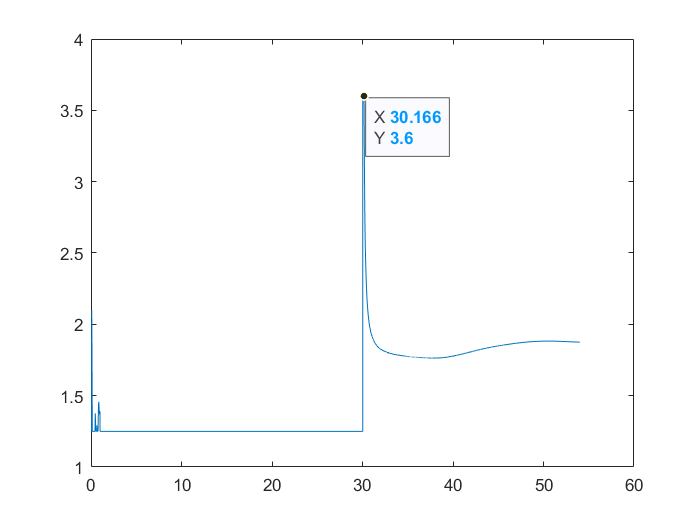

ans =   DataTip (X 30.166, Y 3.6) with properties:

    DataIndex: 30167
     Location: 'southeast'
       Parent: [1×1 Line]

  Show all properties


figure(1)
clf
p1 = plot(Time,RollScalingFactor);
datatip(p1, 30.211 , 3.6)%add data tip to visually see where the data starts becoming reasonable

%then chance the x limit

xl1 = [30.166 Time(end)];

% figure(1)
% clf
% p2 = plot(Time,RearMotionRatio);
% datatip(p2, 32 , 3.6 ) %add data tip to visually see where the data starts becoming reasonable
% %then chance the x limit
% xl2 = [30.027 Time(end)];

title_fontsize = 16;
legend_fontsize = 16;


## Find Means of Motion Ratios

index_xl1_start = find(Time==xl1(1))

index_xl1_start = 30167


mean_RollScalingFactor = mean(RollScalingFactor(index_xl1_start:end))

mean_RollScalingFactor = 1.8420

% LUT_FrontMotionRatio_Data = FrontMotionRatio(index_xl1_start:end);
% LUT_FrontMotionRatio_Breakpoints = Fr2q0_FSusp_Diff_m(index_xl1_start:end);
% LUT_FrontMotionRatio = [LUT_FrontMotionRatio_Breakpoints LUT_FrontMotionRatio_Data]

% index_xl2_start = find(Time==xl2(1))
% 
% mean_RearMotionRatio = mean(RearMotionRatio(index_xl2_start:end))

## Plot Roll Scaling Factor

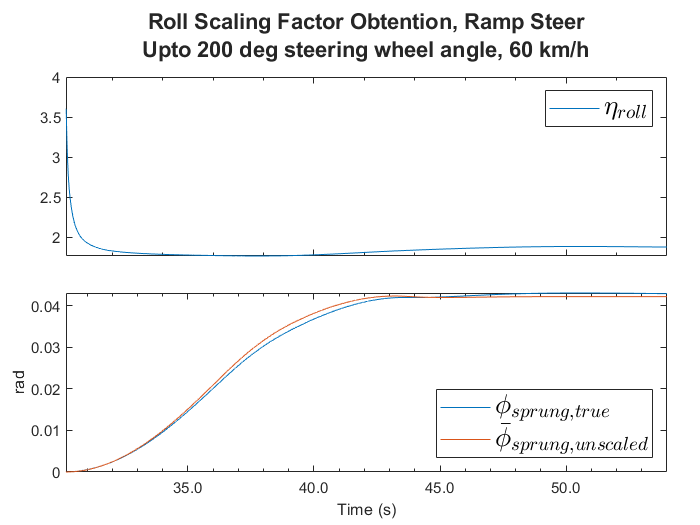

%define x and y axis limits

figure(1)
clf
t1 = tiledlayout(2,1);


ax1a = nexttile;

plot(Time,RollScalingFactor)
legend ("$\eta_{roll}$",'Interpreter','latex','FontSize',legend_fontsize,'location','northeast')

ax1b = nexttile;
plot(Time,CM_Roll_rad,Time,Est_BodyRoll_Static_rad)
legend ('$\phi_{sprung,true}$','$\bar{\phi}_{sprung,unscaled}$','Interpreter','latex','FontSize',legend_fontsize,'location','southeast')
ylabel('rad')
% 
% ax1c = nexttile;
% plot(Time,Est_BodyRoll_CF_deg,...
%     Time,CM_BodyRoll_deg);
% legend ("$\phi_{sprung,est}$","$\phi_{sprung,true}$",'Interpreter','latex', ...
%     'FontSize',11,'location','northwest')
% %    "Ride Height Estimated Sprung Body Roll Angle (deg)", ...  
% ylabel('deg')

%Combine the subplots
linkaxes([ax1a,ax1b],'x')
% 
title(t1, {'Roll Scaling Factor Obtention, Ramp Steer', 'Upto 200 deg steering wheel angle, 60 km/h'})
%title(t3, 'Roll Dynamics Estimation for Sine with Dwell')
t1.Title.FontWeight = 'bold';
% t1.Title.FontSize = 11;
xlabel('Time (s)');
% xticks(xl(1):1:xl(2))
set([ax1a ax1b],'XMinorTick','on')
xtickformat('%.1f')
xticklabels([ax1a],{})

t1.Padding = 'compact';
t1.TileSpacing = 'compact';

xlim(xl1) 

## Plot Rear Motion Ratio

% %define x and y axis limits
% 
% figure(2)
% clf
% t2 = tiledlayout(2,1);
% 
% 
% ax2a = nexttile;
% 
% plot(Time,RearMotionRatio)
% legend ("$\eta_{rear}$",'Interpreter','latex','FontSize',legend_fontsize,'location','northeast')
% 
% ax2b = nexttile;
% plot(Time,CM_RBodyZ_m,Time,Fr2q0_RSusp_Diff_m)
% legend ('$\Delta{Z}_{body,rear}$','$\Delta{L}_{susp,rear}$','Interpreter','latex','FontSize',legend_fontsize,'location','southeast')
% ylabel('meter')
% % 
% % ax1c = nexttile;
% % plot(Time,Est_BodyRoll_CF_deg,...
% %     Time,CM_BodyRoll_deg);
% % legend ("$\phi_{sprung,est}$","$\phi_{sprung,true}$",'Interpreter','latex', ...
% %     'FontSize',11,'location','northwest')
% % %    "Ride Height Estimated Sprung Body Roll Angle (deg)", ...  
% % ylabel('deg')
% 
% %Combine the subplots
% linkaxes([ax2a,ax2b],'x')
% % 
% title(t2, {'Rear Motion Ratio Obtention, Ramp Steer', 'Up to 200 deg steering wheel angle, 60 km/h'})
% %title(t3, 'Roll Dynamics Estimation for Sine with Dwell')
% t2.Title.FontWeight = 'bold';
% % t2.Title.FontSize = 11;
% xlabel('Time (s)');
% % xticks(xl(1):1:xl(2))
% set([ax2a ax2b],'XMinorTick','on')
% xtickformat('%.1f')
% xticklabels([ax2a],{})
% 
% t2.Padding = 'compact';
% t2.TileSpacing = 'compact';
% 
% xlim(xl2) 
